# Image Analysis for Biometric features

Identify points in a frame that correspond the center point of a fish's head by analyzing the intensity characteristics of the larvae. The solution should not depend on threshold values that are manually determined. Investigate the accuracy of your determinations.

## Acquiring images from file

clc;    % Clear the command window.
close all;  % Close all figures (except those of imtool.)
imtool close all;  % Close all imtool figures.
clear;  % Erase all existing variables.
workspace;  % Make sure the workspace panel is showing.

grayfishds = imageDatastore("zebraFish\frames_grey", "FileExtensions",".png", "LabelSource","foldernames");
numImgs = length(grayfishds.Labels);

numFish = 8;
numProcessed = 0;
totalFishFound = 0;

for i = 1:1
    img = readimage(grayfishds, 1);
end

## Convert Image to Grayscale

Despite the image already being in grayscale, matlab still considers the image an rgb even though the rgb values are all the same within each pixel. Converting the to grayscale gets rid of the rgb and allows the usage of functions that require grayscale images.

    grayimg = im2gray(img);

## Edge Detection

Using edge detection to see if it helps separate the fish from the background.

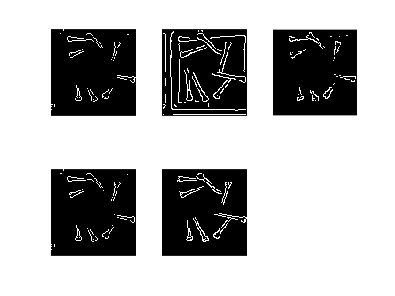

    edges_prewitt = edge(grayimg,"prewitt");
    edges_canny = edge(grayimg,"canny");
    edges_roberts = edge(grayimg,"roberts");
    edges_sobel = edge(grayimg,"sobel");
    edges_approxcan = edge(grayimg,"approxcanny");

    figure;
    subplot(2,3,1);
    imshow(edges_prewitt);
    subplot(2,3,2);
    imshow(edges_canny);
    subplot(2,3,3);
    imshow(edges_roberts);
    subplot(2,3,4);
    imshow(edges_sobel);
    subplot(2,3,5);
    imshow(edges_approxcan);
    linkaxes;


    [edges_prewitt2, edge_threshold] = edge(grayimg, "canny");

    sensitivity = 0.18

sensitivity = 0.1800

    lower = 0.1

lower = 0.1000

    sigma = 0.01

sigma = 0.0100

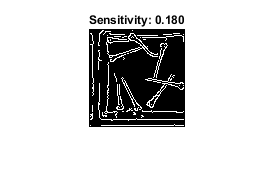

%     
    edges_prewitt2 = edge(grayimg, "canny",[lower,sensitivity],sigma);
    figure;
    test = imshow(edges_prewitt2);
    title(sprintf("Sensitivity: %.03f", sensitivity));

    

    BW3 = uint8(edges_prewitt2*255);
    edge_gray = grayimg+BW3;
    figure;
    subplot(2,2,1)
    imshow(edge_gray);
    

## Multithresh and Image segmentation

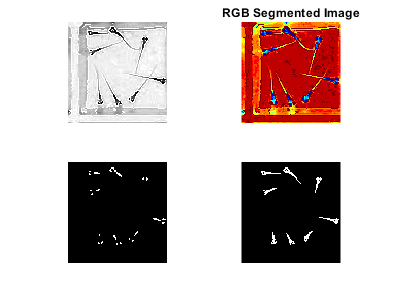

    thresh = multithresh(edge_gray, 15);
    seg_I = imquantize(edge_gray,thresh);
    RGB = label2rgb(seg_I);
    threshedimg= im2gray(RGB);
    subplot(2,2,2)
    imshow(RGB);
    axis off
    title('RGB Segmented Image');
    eyesregions = (seg_I == 1 );
   
    subplot(2,2,3)
    imshow(eyesregions);
    
    headregions = ( seg_I == 1 | seg_I == 2 | seg_I == 3 | seg_I == 4 | seg_I == 5 | seg_I == 6 | seg_I == 7);
    headregions = bwareaopen(headregions, 10);
    subplot(2,2,4)
    imshow(headregions)
    linkaxes;

    bwconncomp(headregions,4)

ans = struct with fields:
    Connectivity: 4
       ImageSize: [98 96]
      NumObjects: 16
    PixelIdxList: {[34×1 double]  [2×1 double]  [27×1 double]  [26×1 double]  [43×1 double]  [4284]  [28×1 double]  [5310]  [5409]  [5508]  [5607]  [30×1 double]  [3×1 double]  [30×1 double]  [4×1 double]  [38×1 double]}


    [x, y] = find(seg_I==1);

